# Data Cleaning Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 09/03/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Enviroment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

Set Image export path:

% use your default user path to create the filename and path
exportName = ''
exportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Exploration/',exportName);

## 2. Data

 Data file naming convention:


$$\texttt{source\_\_data\_type\_\_data\_label.extension} 

$$


Example:


$$\texttt{bloomberg\_\_ticker\_cashflow\_data\_\_sa\_listed\_bonds.xlsx}$$


List of needed data currently:

- 
$$\texttt{bloomberg\_\_ticker\_cashflow\_data\_\_sa\_listed\_bonds.xlsx}$$


- 
$$\texttt{bloomberg\_\_ticker\_fundemental\_data\_\_sa\_listed\_bonds.xlsx}
$$


- 
$$\texttt{bloomberg\_\_ticker\_market\_data\_\_albi\_index.xlsx}
$$


trying to fix SAGDP issues at an import level

% opts = detectImportOptions(fileName)
% disp([opts.VariableNames' opts.VariableTypes'])
% opts.VariableTypes{2} = 'double'; 
% disp([opts.VariableNames' opts.VariableTypes'])

% define columns to keep from each sheet
% varsToKeep = {'PX_LAST'};
% % create sheetName var to loop through in the file
% excelSheetNames = sheetnames(fileName);
% % Preallocate cell array for storage before looping
% SIG_data = cell(size(excelSheetNames));
% % Load the dataset by sheet
% for sheet = 1:numel(excelSheetNames)
%     % Read the sheet and filter for numeric variables only
%     sheetData = readtable(fileName, 'Sheet', excelSheetNames{sheet}, 'Range', 'A6', 'VariableNamingRule', 'preserve', 'VariableNamesRange', 'A6');
%     sheetData = sheetData(:,isnumeric(sheetData{:, :}));
%     % Keep only columns specified in varsToKeep
% %     sheetData = sheetData(:,varsToKeep);
%     % Convert to timetable object and assign the ticker as the timetable Description
% %     SIG_data{sheet} = table2timetable(sheetData, 'RowTimes', 1:size(sheetData,1), 'Description', excelSheetNames{sheet});
% end

### 2.1 SIGNAL DATA: Load data: Automate file imports (works but SAGDP is char)

**Set Directories **

% use your default user path to create the filename and path
fileName = "DATA-BB-SIG-M-20000223-20230323.xlsx";
fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/SIGNAL',fileName);

Import per sheet

% % % ############## RECODE to automate imports #####################

% define columns to keep from each sheet
varsToKeep = {'PX_LAST'};

% create sheetName var to loop through in the file
excelSheetNames = sheetnames(fileName);
% Preallocate cell array for storage before looping
SIG_data{numel(excelSheetNames)} = [];
% Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
SIG_data{sheet} = readtimetable(fileName,'Sheet',excelSheetNames{sheet},VariableNamingRule='preserve', VariableNamesRange ='A6', VariableDescriptionsRange = 'B4',Range='A6');
% Assign the ticker as the timetable Description
SIG_data{sheet}.Properties.Description = excelSheetNames{sheet};
% from all columns remove all but 'varsToKeep'
varsToRemove = setdiff(SIG_data{sheet}.Properties.VariableNames, varsToKeep);
if ~isempty(varsToRemove)
    SIG_data{sheet} = removevars(SIG_data{sheet}, varsToRemove);
end
end

#### 2.1.1 Address data types and frequencies

- SA GDP data type has text due to the NAs imported. Needs to be changed to numeric. 

- SA GDP data is Quarterly -> needs to be changed using cubic-spline interpolation to monthly points

% Replace '#N/A N/A' with NaN
SAGDP_table = SIG_data{2}

for entry = 1:height(SAGDP_table)
    if strcmp(SAGDP_table{entry,1}{1}, '#N/A N/A')       
        SAGDP_table.PX_LAST{entry} = str2num('NA');
%         = str2double(SAGDP_table{entry,1});
%     elseif ischar(SAGDP_table{entry,1}{1})
%         SAGDP_table{entry,1}{1} = strrep(SAGDP_table{entry,1}{1}, ',', '.');
%         SAGDP_table{entry,1} = str2double(SAGDP_table{entry,1}{1});
    end
end 
% 
% for entry = 1:height(SAGDP_table)
% 
%     if strcmp(SAGDP_table{entry,1}{1}, '#N/A N/A')       
%         SAGDP_table{entry,1} = {NaN};
% %     elseif SAGDP_table{entry,1}{1} == isa(SAGDP_table{entry,1}{1},'char')
% %          SAGDP_table{entry,1} = str2double(SAGDP_table{entry,1}{1});
%     end
% end
SAGDP_table
% strcmp(SAGDP_table{entry,1}{1}, '#N/A N/A')) = SAGDP_table{entry,1}
% % Replace '#N/A N/A' with NaN
% SAGDP_table(strcmp(SAGDP_table{:,1}{1}, '#N/A N/A')) = {NaN};
% 
% Convert remaining values to doubles
% SAGDP_table{:,1} = str2double(SAGDP_table{:});

% % Replace any empty cells with NaN
% SAGDP_table(cellfun(@isempty, SAGDP_table)) = {NaN};

#### 2.1.2 Clean and convert into a single timetable by synchronize dates

% Synchronize all timetable objects in the cell array
SIG_dataTable = synchronize(SIG_data{:});
% rename variables
SIG_dataTable.Properties.VariableNames = excelSheetNames
% Display the synchronized timetable
disp(SIG_dataTable);

%######## Dropping GDP for now until ######3
SIG_dataTable = removevars(SIG_dataTable, "SAGDPANN Index");

When looking at the timetable we notice that there are inconsistencies with when certain signal indices are reported. 

#### 2.1.3 Missing data

 Plot before removing NA values: consistent with data not reported over weekends and holidays.

% missing data to plot in array
tickers = {'JALSHTR Index', 'OEZAKLAP Index', 'SACPIYOY Index', 'SAMYM3Y Index', 'JPEIGLBL Index', 'USDZAR Curncy', "NAPMPMI Index", "VIX Index", "SPX Index", "US0003M Index", "JIBA3M Index", "SAVIT40 Index"};
na_array = transpose(isnan(table2array(SIG_dataTable)));
ax = axes;
spy(na_array, 'black-',5);
set(gca,'ytick',1:12,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Signals");
xlabel("Date Index");
title("Missing Data prior to date alignment");
sig_NAplot = gca

Export NA Data plot

exportName = 'SIG_NAdata_plot.pdf';
exportgraphics(sig_NAplot,fullfile(exportpath,exportName),'Resolution',300)

#### 2.1.4 Exporting sample chunck of data to change to latex table

% Set time range to subset
TR_general = timerange('30-Sep-2009','31-Dec-2010')
sig_sample_tab = SIG_dataTable(TR_general,:);
%  = tail(SIG_dataTable)

writetimetable(sig_sample_tab,'sig_sample_tab.xlsx')

Fixing the inconsistent dates in the timetable objects by shifting the timedate array of the individual state signal variables before synchronizing


for signal = 1:width(SIG_data)
    SIG_data{1,signal}.Dates = dateshift(SIG_data{1,signal}.Dates, 'end', 'month')
end
SIG_aligned_data = SIG_data

% Synchronize timetable objects 
SIG_aligned_dataTable = synchronize(SIG_aligned_data{:});
% rename variables
SIG_aligned_dataTable.Properties.VariableNames = excelSheetNames
% Display the synchronized timetable
disp(SIG_aligned_dataTable);

%######## Dropping GDP for now until ######3
SIG_aligned_dataTable = removevars(SIG_aligned_dataTable, "SAGDPANN Index");

Plotting date adjusted data for signal data

% missing data to plot in array
tickers = {'JALSHTR Index', 'OEZAKLAP Index', 'SACPIYOY Index', 'SAMYM3Y Index', 'JPEIGLBL Index', 'USDZAR Curncy', "NAPMPMI Index", "VIX Index", "SPX Index", "US0003M Index", "JIBA3M Index", "SAVIT40 Index"};
na_array = transpose(isnan(table2array(SIG_aligned_dataTable)));
ax = axes;
spy(na_array, 'black-',5);
set(gca,'ytick',1:12,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Signals");
xlabel("Date Index");
title("Missing Data POST date alignment");

### 2.2 ASSET CLASS DATA: Load data: Automate file imports 

Import data from excel spreed sheet build using Bloomberg Terminal 

**Set Directories **

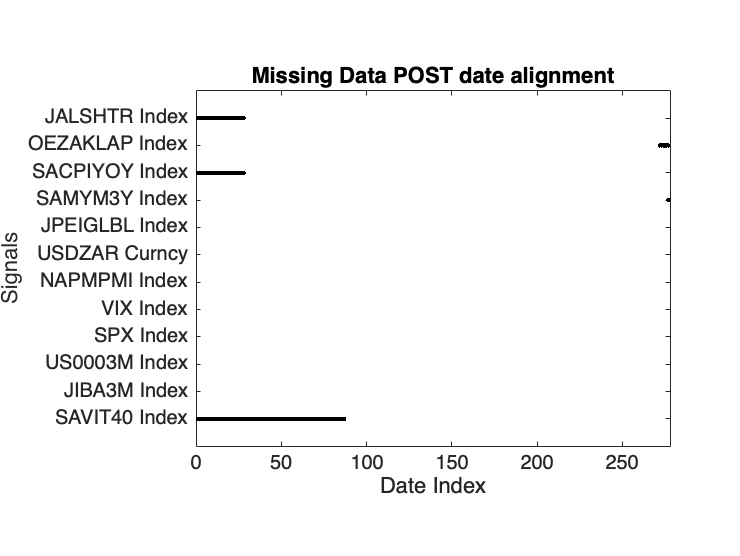

% use your default user path to create the filename and path
fileName = "DATA-BB-ASSETCL-IDX-M-20000223-20230323.xlsx";

fileName = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BLOOMBERG/ASSETCLASS',fileName);

Import from single sheet

ASSETCL_dataTable = readtimetable(fileName, VariableNamingRule='preserve', VariableNamesRange ='A4', VariableDescriptionsRange = 'B5',Range='A4');

#### 2.2.1 Missing data

 Plot before removing NA values: consistent with data not reported over weekends and holidays.

% missing data to plot in array
tickers = ASSETCL_dataTable.Properties.VariableNames;
na_array = transpose(isnan(table2array(ASSETCL_dataTable)));
ax = axes;

spy(na_array, 'black-',5);
set(gca,'ytick',1:5,'yticklabel',tickers);
pbaspect([8 6 1]);
ylabel("Assets");
xlabel("Date Index");
title("Missing Data");
assetcl_NAplot = gca

Export NA Data plot

exportName = 'ASSETCL_NAdata_plot.pdf'
exportgraphics(assetcl_NAplot,fullfile(exportpath,exportName),'Resolution',300)

Sequentually load files 

Currency 

 **Indices**: 

Market Sectors

Financials -> Fini (& TR)

Industrial -> Indi (& TR)

Resources -> Resi (need to get TR on BB. Ticker for TR = J310T)

Bonds -> Albi 

% Preallocate cell array before looping


Macro - eco

% SA Real Gross Domestic Product


Sequentually load files 

- 
$$\texttt{bloomberg\_\_ticker\_cashflow\_data\_\_sa\_listed\_bonds.xlsx}$$


          2. $\texttt{bloomberg\_\_ticker\_fundemental\_data\_\_sa\_listed\_bonds.xlsx}
$

#### Selected Desired Fields

Find Tickers in the column names and keep the TRI only of sheets JSE ICB 0500 Indices and JSE Various Indices.

[strncmp](https://www.mathworks.com/help/matlab/ref/strncmp.html) is one of the text comparison functions that can be used. Read more [here](https://www.mathworks.com/help/matlab/matlab_prog/string-comparisons.html).

%%% USE TIM'S CODE

# tick2ret

Convert price series to return series

% [resi_returns,resi_intervals] = tick2ret(bloomberg__ticker_market_data__resi20_index)
% % subplot(4,1,1);
% ax = axes;
% spy(transpose(isnan(table2array(resi_returns))));
% ylabel("Assets Index")
% xlabel("Date Index")
% title("Missing Data")
% % [left bottom width height]
% ax.OuterPosition = [ax.OuterPosition(1:3) ax.OuterPosition(4)];

### Needed Functions

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)

- [https://en.wikipedia.org/wiki/Risk_parity](https://en.wikipedia.org/wiki/Risk_parity)